
%data=data_tabelle.Zyklen;
%data_tabelle=readtable("viskositaet.xlsx");
%data=data_tabelle.Viskositaet;

%data=randn([20,1])+4;
data=rand([20,1])+3;
a=1;
%x-Daten, Anzahl Datenwerte etc.%data_tabelle=readtable("Lebensdauer_Bueroklammer.csv");
    anzahl=length(data);
    x=(min(data)-a:0.1:max(data)+a);

%Bei allen Optionen ist der Default-Wert das 95% Konfidenzintervall, ändern
%mit z.B. "Alpha",0.01

%Konfidenzintervalle der Parameter von Verteilungen
pd_norm=fitdist(data,'Normal')

pd_norm =   NormalDistribution

  Normal distribution
       mu =  3.42688   [3.28826, 3.5655]
    sigma = 0.296189   [0.225249, 0.432606]


ci_normal=paramci(pd_norm,'Alpha',0.05)

ci_normal =     3.2883    0.2252
    3.5655    0.4326


pd_weibull=fitdist(data,'Weibull')

pd_weibull =   WeibullDistribution

  Weibull distribution
    A = 3.56624   [3.42796, 3.7101]
    B = 11.7881   [8.52126, 16.3074]


ci_weibull=paramci(pd_weibull,'Alpha',0.05)

ci_weibull =     3.4280    8.5213
    3.7101   16.3074


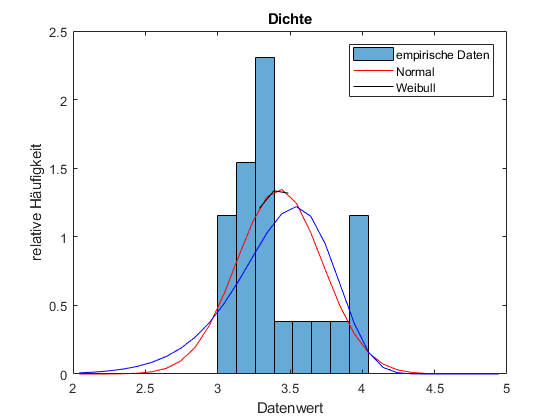


figure(1)
histogram(data,2*round(sqrt(anzahl)),'Normalization','pdf')
hold on
plot(x,normpdf(x, pd_norm.mu,pd_norm.sigma),'Color','r')
plot((ci_normal(1):0.1:ci_normal(2)),normpdf((ci_normal(1):0.1:ci_normal(2)), pd_norm.mu,pd_norm.sigma),"Color","black")
plot(x,wblpdf(x, pd_weibull.A,pd_weibull.B),'Color','b')

title('Dichte')
xlabel('Datenwert')
ylabel('relative Häufigkeit')
legend('empirische Daten', 'Normal','Weibull')
hold off

%Konfidenzintervalle über Tests
%t-Verteilung:
[~,~,t_ci,t_stats]=ttest(data)

t_ci =     3.2883
    3.5655


t_stats = struct with fields:
    tstat: 51.7421
       df: 19
       sd: 0.2962


%Verteilungsunabhängige Konfidenzintervalle für Quantile
%Berechnung des Konfidenzintervalls für den Median (McGill 1978)
ci_lower=median(data)-1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)

ci_lower = 3.1906

ci_upper=median(data)+1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)

ci_upper = 3.4762

ci_median=[ci_lower,ci_upper]

ci_median =     3.1906    3.4762


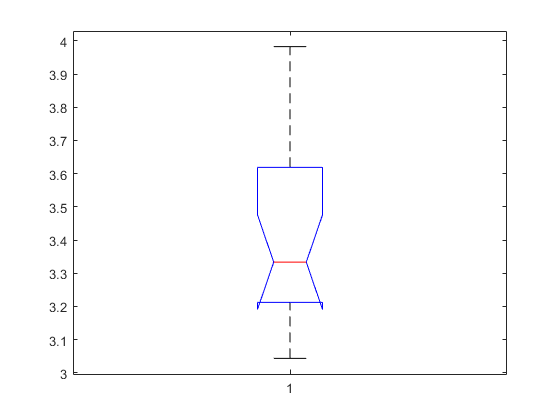


%Veranschaulichung der Verteilung incl. Konfidenzintervall vom Median im
%Boxplot (Matlab verwendet obige Formel)
boxplot(data,'Notch','on')

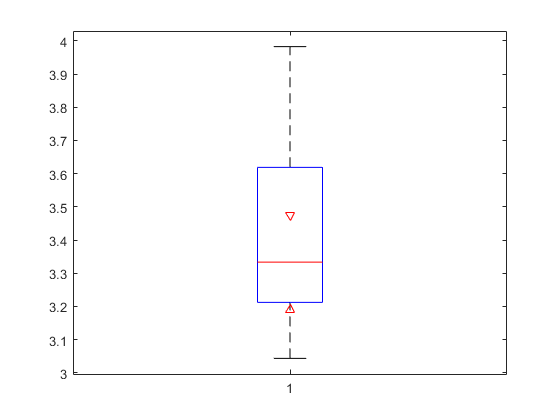

boxplot(data,'Notch','marker')

%Bootstrapping 
[boot_stats, data_boot]=bootstrp(100,@median,data)

boot_stats =     3.2692
    3.2758
    3.3442
    3.2869
    3.2803
    3.2572
    3.4469
    3.2848
    3.2692
    3.3613


data_boot =     14    12    14     6     4     2     2    19     5     3    18     9    19     6    11     7    12     6     9    11    10     5     4    20    13    20    20    10     2    17    19    17     4    18     5     1     2     8    10     2     1     5    12    13    10    14     2    10     7    12
     4     8    15     2     9     8    19     8     9     7     1    17    15     8    13    11     9    17     2    13    12    19     3     4     7    12    16    16    13    14     2    18     7    19    10    16    17    20    19    15    11     6    12    15     3     4    14     5    10    10
    10    10     1    16     9    10    19    15    17    15    19    11    15    13     4     6    10     9     4    10    12    16     5    10     1     6    15     8     8     1     1     6    17    10    17    17    16    12    12    10    17    11    19    18    11    10    14     1    16    14
     4     4     9     6    14     5    15    20    15    13     4    15     1    11 

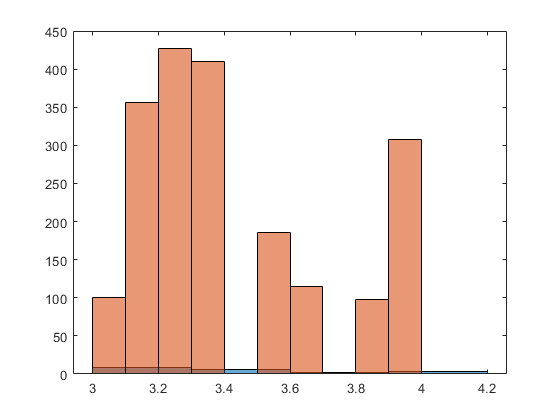

figure(4)
histogram(data)
hold on
histogram(data(data_boot))
hold off

ci_boot_mean=bootci(100,{@mean,data})

ci_boot_mean =     3.3122
    3.5624


[ci_boot_median,stats]=bootci(100,{@median,data})

ci_boot_median =     3.2577
    3.5558


stats =     3.2803
    3.3364
    3.2577
    3.3116
    3.3553
    3.3334
    3.2803
    3.3769
    3.3613
    3.3116
